%{

    run_1b_2.mlx
    ------------
    This code serves as the extension part to our stochastic life cycle model with endogenous labor supply.

%}
clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/nguyenhoangminh/Desktop/ps2 - task 1b'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/nguyenhoangminh/Desktop/ps2 - task 1b 




nu_vals = [0.5, 1.0, 1.5, 2.0];
gamma_fixed = 1.00;

% Load base model
par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;

fprintf('Descriptive stats by \\nu (\\gamma = %.2f):\n', gamma_fixed);

Descriptive stats by \nu (\gamma = 1.00):


fprintf(['  \\nu     | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n' ...
                'Mean(N)  Min(N)   Max(N)   Std(N)']);

  \nu     | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)
Mean(N)  Min(N)   Max(N)   Std(N)

fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------


figure(1); clf;

for i = 1:length(nu_vals)
    par = par0;
    par.nu = nu_vals(i);
    par.gamma = gamma_fixed;

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    mean_n = mean(lcp_n, 'omitnan');
    min_n = min(lcp_n, [], 'omitnan');
    max_n = max(lcp_n, [], 'omitnan');
    std_n = std(lcp_n, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f || %.4f  %.4f  %.4f  %.4f\n', ...
        par.nu, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a,...
        mean_n, min_n, max_n, std_n);

    subplot(3,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\nu = %.2f', par.nu));

    subplot(3,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\nu = %.2f', par.nu));

    subplot(3,1,3); hold on;
    plot(ages, lcp_n, 'DisplayName', sprintf('\\nu = %.2f', par.nu));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.50   | 9.5196  1.5467  22.2676  6.8088  || 9.8297  0.0000  30.0000  9.0005 || 0.4956  0.0000  0.9899  0.3933


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 5.8196  1.5467  16.9077  4.5824  || 11.3743  0.0000  29.9997  8.8397 || 0.2716  0.0000  0.9469  0.2325


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.50   | 5.0085  1.5467  15.2570  3.8183  || 11.0015  0.0000  29.9993  8.9002 || 0.2255  0.0000  0.9735  0.2011


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 2.00   | 4.4036  1.5467  13.1873  2.9798  || 10.4279  0.0000  30.0000  8.9861 || 0.1973  0.0000  0.9780  0.1800


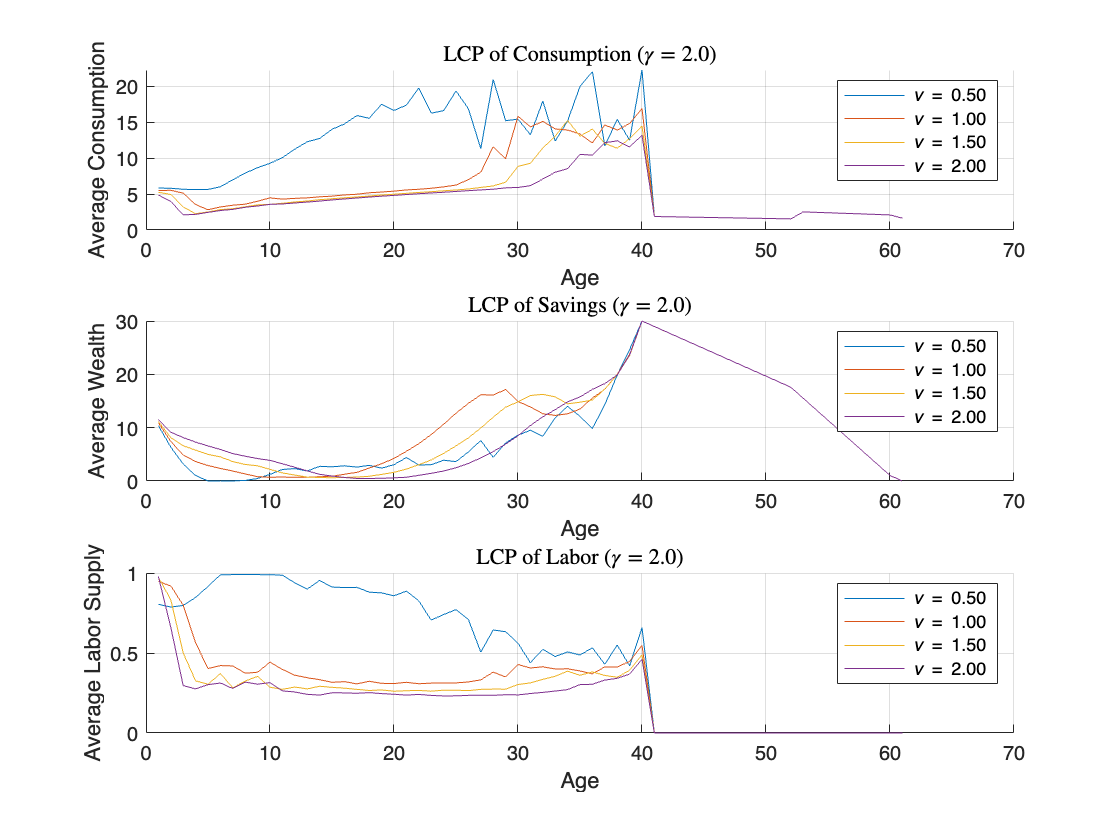

% Final plot touches for nu variation
subplot(3,1,1);
title('LCP of Consumption ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(3,1,2);
title('LCP of Savings ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;
subplot(3,1,3);
title('LCP of Labor ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Labor Supply'); grid on; legend show;


gamma_vals = [1.0, 2.0, 3.0, 4.0];
nu_fixed = 1.0;

% Load base model
par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;

fprintf('Descriptive stats by gamma (nu = %.2f):\n', nu_fixed);

Descriptive stats by gamma (nu = 1.00):


fprintf(['  gamma    | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n']);

  gamma    | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)


fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------


figure(1); clf;

for i = 1:length(gamma_vals)
    par = par0;
    par.gamma = gamma_vals(i);
    par.nu = nu_fixed;

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    mean_n = mean(lcp_n, 'omitnan');
    min_n = min(lcp_n, [], 'omitnan');
    max_n = max(lcp_n, [], 'omitnan');
    std_n = std(lcp_n, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f || %.4f  %.4f  %.4f  %.4f\n', ...
        par.gamma, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a,...
        mean_n, min_n, max_n, std_n);

    subplot(3,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));

    subplot(3,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));

    subplot(3,1,3); hold on;
    plot(ages, lcp_n, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 5.8196  1.5467  16.9077  4.5824  || 11.3743  0.0000  29.9997  8.8397 || 0.2716  0.0000  0.9469  0.2325


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 2.00   | 6.6495  1.5467  20.9419  5.8613  || 13.0048  0.0000  29.9986  7.7121 || 0.3026  0.0000  0.9740  0.2589


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 3.00   | 7.0368  1.5459  19.5301  6.3101  || 13.4233  0.0000  29.9717  7.4605 || 0.3142  0.0000  0.9782  0.2570


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 4.00   | 7.2301  1.5449  20.2320  6.6292  || 13.2466  0.0000  29.9383  7.7545 || 0.3229  0.0000  0.9790  0.2626


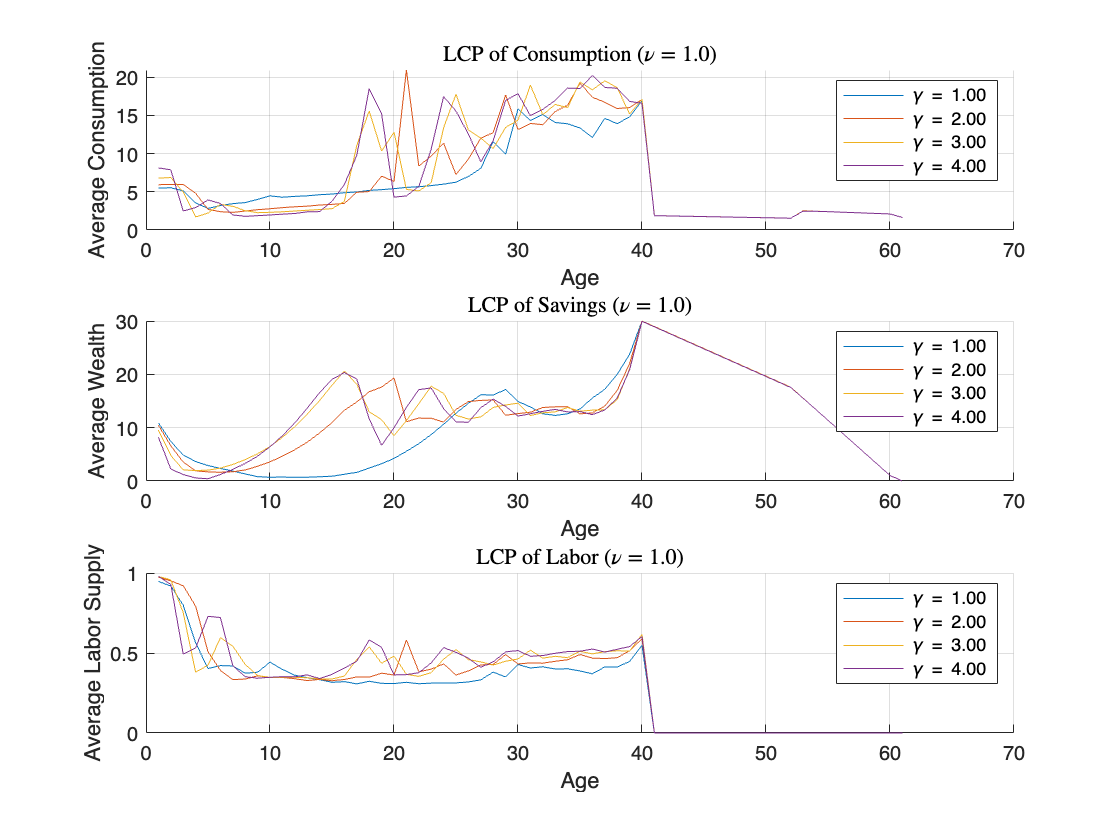

% Final plot touches for nu variation
subplot(3,1,1);
title('LCP of Consumption ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(3,1,2);
title('LCP of Savings ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;

subplot(3,1,3);
title('LCP of Labor ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Labor Supply'); grid on; legend show;

% === Load and process real data ===
real_data = readtable('real_data_22.csv', 'VariableNamingRule', 'preserve');

ages_real = real_data.m1ac5 - 24;
valid_idx = ages_real <= 61;

wealth_real = real_data.('Value of Household Asset');
cons_real = real_data.('Average Annual Consumption - All Categories');
labor_real = real_data.('Average Household Working Hours');

% Set labor to 0 after retirement
labor_real(ages_real >= 41) = 0;

% Normalize consumption and wealth
wealth_real_norm = wealth_real / wealth_real(1);
cons_real_norm = cons_real / cons_real(1);

% Trim data
ages_real_trimmed = ages_real(valid_idx);
wealth_real_trimmed = wealth_real_norm(valid_idx);
cons_real_trimmed = cons_real_norm(valid_idx);
labor_real_trimmed = labor_real(valid_idx);

% === Simulate model ===
par0 = model.setup();
par0 = model.gen_grids(par0);
sol = solve.lc(par0);

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


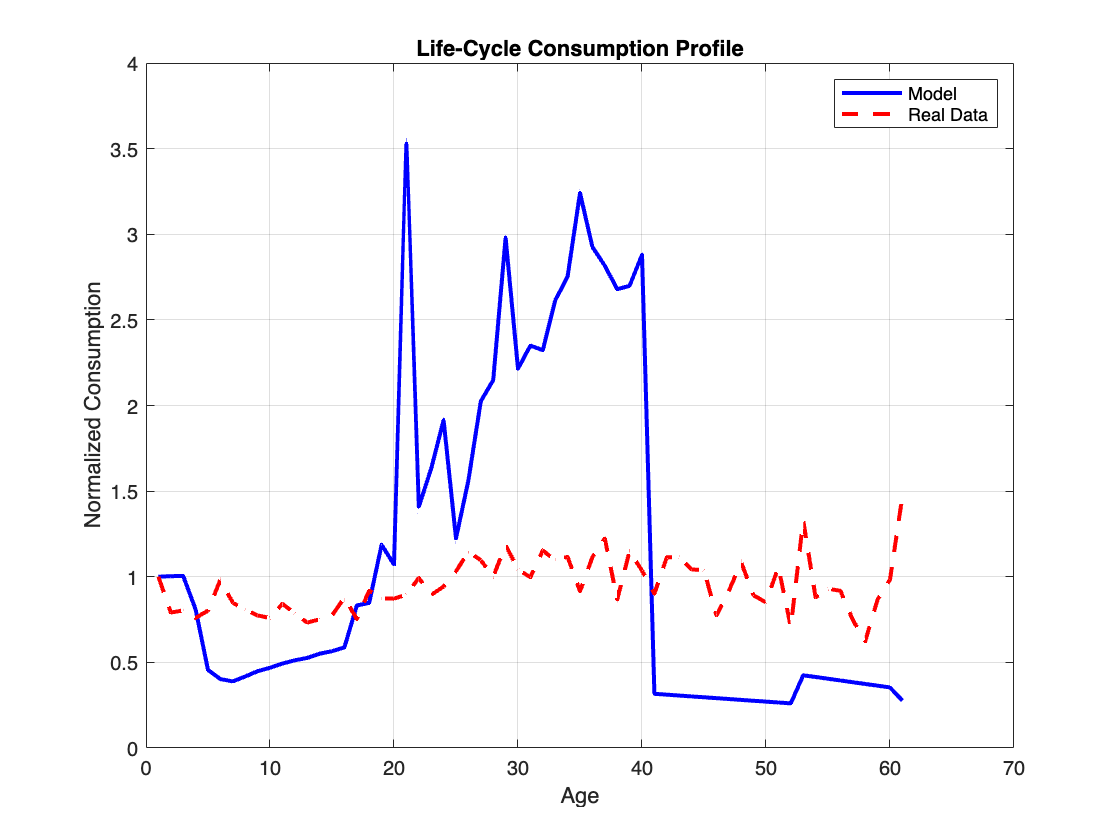

sim = simulate.lc(par0, sol);

ages_model = (1:par0.T)';
lcp_c = nan(par0.T,1);
lcp_a = nan(par0.T,1);
lcp_n = nan(par0.T,1);

for t = 1:par0.T
    lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    lcp_n(t) = mean(sim.nsim(sim.tsim == t), 'omitnan');
end

% === Plot 1: Consumption ===
figure;
plot(ages_model, lcp_c / lcp_c(1), 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, cons_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Normalized Consumption');
legend('Model', 'Real Data');
title('Life-Cycle Consumption Profile');
grid on;

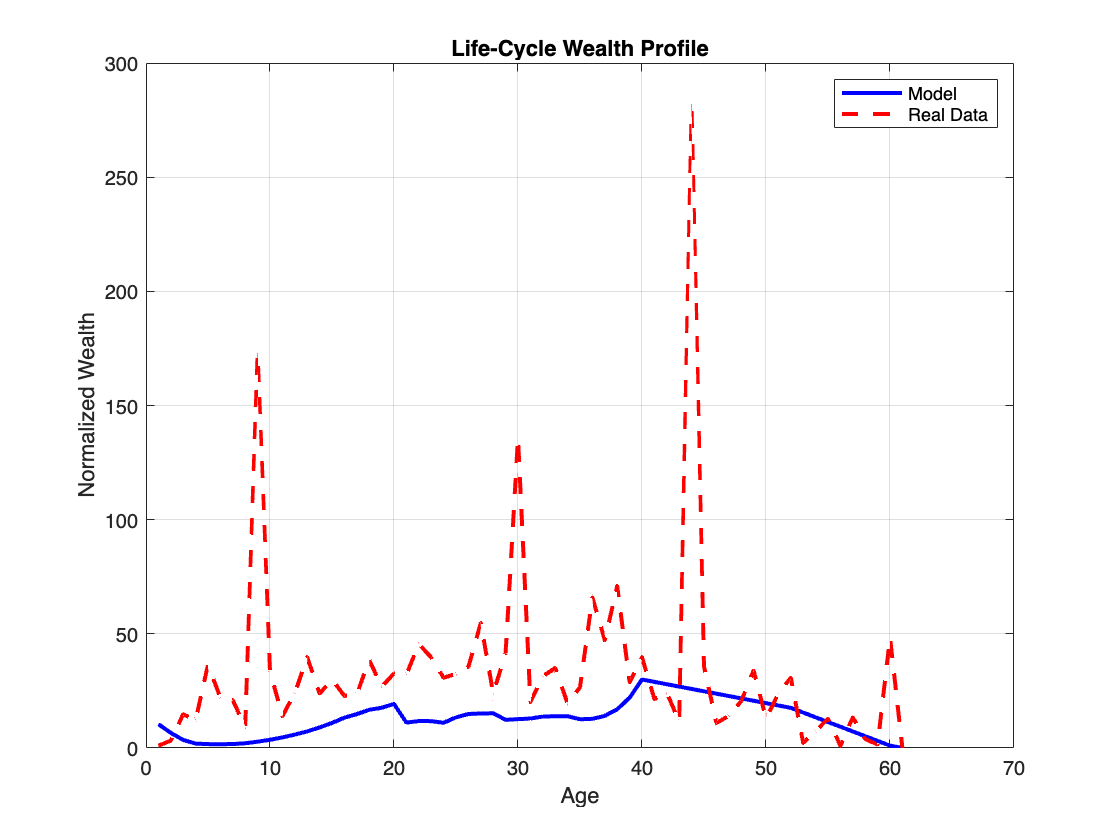


% === Plot 2: Wealth ===
figure;
plot(ages_model, lcp_a, 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, wealth_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Normalized Wealth');
legend('Model', 'Real Data');
title('Life-Cycle Wealth Profile');
grid on;

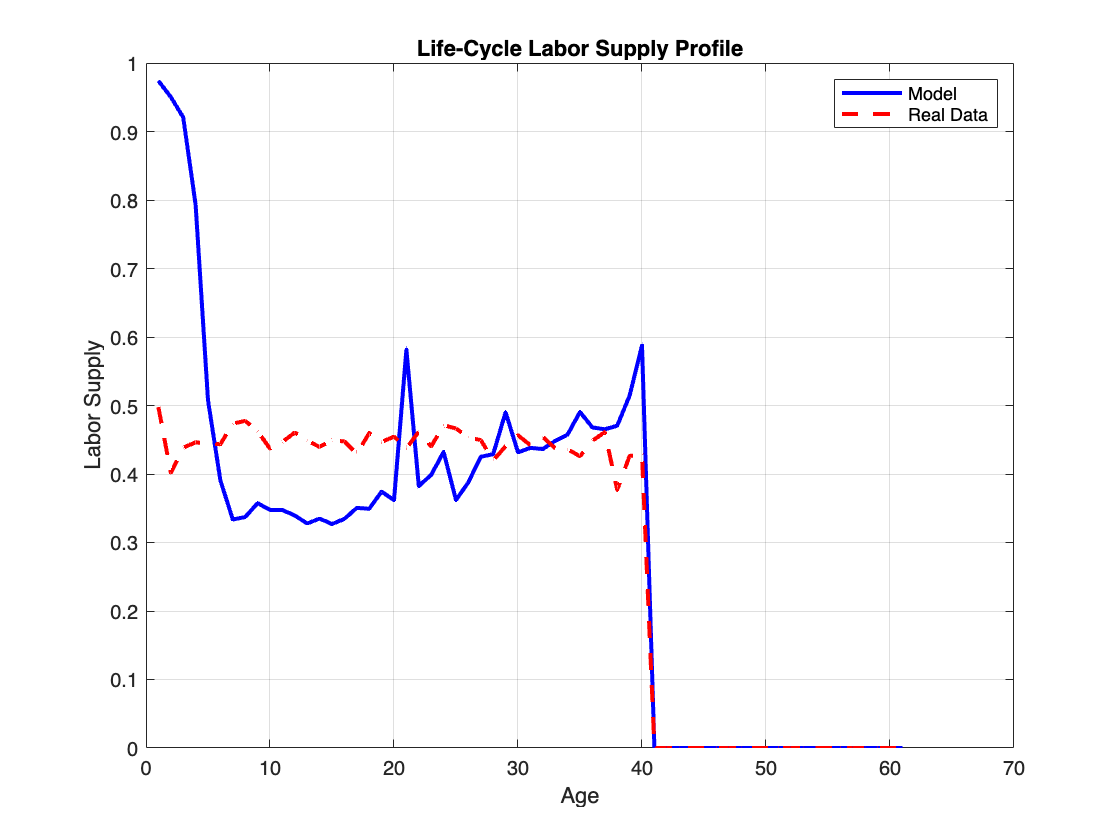


% === Plot 3: Labor Supply ===
figure;
plot(ages_model, lcp_n, 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, labor_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Labor Supply');
legend('Model', 'Real Data');
title('Life-Cycle Labor Supply Profile');
grid on;


% === Descriptive Stats: Real Data ===
mean_wealth = mean(wealth_real_trimmed, 'omitnan');
min_wealth  = min(wealth_real_trimmed);
max_wealth  = max(wealth_real_trimmed);
std_wealth  = std(wealth_real_trimmed, 'omitnan');

mean_cons = mean(cons_real_trimmed, 'omitnan');
min_cons  = min(cons_real_trimmed);
max_cons  = max(cons_real_trimmed);
std_cons  = std(cons_real_trimmed, 'omitnan');

mean_labor = mean(labor_real_trimmed, 'omitnan');
min_labor  = min(labor_real_trimmed);
max_labor  = max(labor_real_trimmed);
std_labor  = std(labor_real_trimmed, 'omitnan');

fprintf('\nDescriptive Statistics for Real Data (Normalized):\n');


Descriptive Statistics for Real Data (Normalized):


fprintf('Consumption: Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_cons, min_cons, max_cons, std_cons);

Consumption: Mean = 0.9450, Min = 0.6233, Max = 1.4704, Std = 0.1630


fprintf('Wealth     : Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_wealth, min_wealth, max_wealth, std_wealth);

Wealth     : Mean = 33.9189, Min = 0.0000, Max = 279.2326, Std = 42.3723


fprintf('Labor      : Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_labor, min_labor, max_labor, std_labor);

Labor      : Mean = 0.2924, Min = 0.0000, Max = 0.4976, Std = 0.2143



real_table = table(...
    [mean_cons; min_cons; max_cons; std_cons], ...
    [mean_wealth; min_wealth; max_wealth; std_wealth], ...
    [mean_labor; min_labor; max_labor; std_labor], ...
    'VariableNames', {'Consumption', 'Wealth', 'Labor'}, ...
    'RowNames', {'Mean', 'Min', 'Max', 'Std'});

disp('Real Data Summary Table:');

Real Data Summary Table:


disp(real_table);

            Consumption    Wealth     Labor 
            ___________    ______    _______

    Mean      0.94503      33.919    0.29245
    Min       0.62326           0          0
    Max        1.4704      279.23    0.49762
    Std       0.16296      42.372    0.21429




% === Descriptive Stats: Simulated Data ===
mean_c_sim = mean(lcp_c/lcp_c(1), 'omitnan');
min_c_sim  = min(lcp_c/lcp_c(1));
max_c_sim  = max(lcp_c/lcp_c(1));
std_c_sim  = std(lcp_c/lcp_c(1), 'omitnan');

mean_a_sim = mean(lcp_a, 'omitnan');
min_a_sim  = min(lcp_a);
max_a_sim  = max(lcp_a);
std_a_sim  = std(lcp_a, 'omitnan');

mean_n_sim = mean(lcp_n, 'omitnan');
min_n_sim  = min(lcp_n);
max_n_sim  = max(lcp_n);
std_n_sim  = std(lcp_n, 'omitnan');

fprintf('\nDescriptive Statistics for Simulated Data:\n');


Descriptive Statistics for Simulated Data:


fprintf('Consumption: Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_c_sim, min_c_sim, max_c_sim, std_c_sim);

Consumption: Mean = 1.1204, Min = 0.2606, Max = 3.5285, Std = 0.9876


fprintf('Wealth     : Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_a_sim, min_a_sim, max_a_sim, std_a_sim);

Wealth     : Mean = 13.0048, Min = 0.0000, Max = 29.9986, Std = 7.7121


fprintf('Labor      : Mean = %.4f, Min = %.4f, Max = %.4f, Std = %.4f\n', ...
    mean_n_sim, min_n_sim, max_n_sim, std_n_sim);

Labor      : Mean = 0.3026, Min = 0.0000, Max = 0.9740, Std = 0.2589



sim_table = table(...
    [mean_c_sim; min_c_sim; max_c_sim; std_c_sim], ...
    [mean_a_sim; min_a_sim; max_a_sim; std_a_sim], ...
    [mean_n_sim; min_n_sim; max_n_sim; std_n_sim], ...
    'VariableNames', {'Consumption', 'Wealth', 'Labor'}, ...
    'RowNames', {'Mean', 'Min', 'Max', 'Std'});

disp('Simulated Data Summary Table:');

Simulated Data Summary Table:


disp(sim_table);

            Consumption    Wealth     Labor 
            ___________    ______    _______

    Mean       1.1204      13.005    0.30257
    Min        0.2606           0          0
    Max        3.5285      29.999    0.97401
    Std       0.98757      7.7121    0.25889

